clc,clear
%%Demo for LU factorization
%%LU分解函数 Doolittle 分解
n=5;
% A=[0.0591885387896972	0.996096640771298	2.38995183630680	-1.82903670221613	1.59382135488806;
% -0.265174371656514	0.102891383623264	0.0772456795913396	2.09145219348348	0.155205633826749;
% 0.857692607972956	-1.91838187611468	0.375607450233409	0.359093122201244	0.178595629002979;
% 0.545686171692389	-0.131067824281041	0.395564169367877	-0.794344747026787	-0.337730845992083;
% 1.85375176248034	-0.768631666817079	-0.112499088960486	-0.227311640661342 -1.52499188975933];
A=randn(n);
[L,U]=LU(A);
B=L*U;
L*U-A

ans = 1.0e-15 *

         0         0         0         0         0
         0         0         0    0.0555         0
         0         0         0         0         0
         0         0    0.0555   -0.0833   -0.2220
         0         0         0    0.0063         0


fprintf('||L*U-A||=%f\n',norm(L*U-A));% 默认为矩阵的二范数

||L*U-A||=0.000000


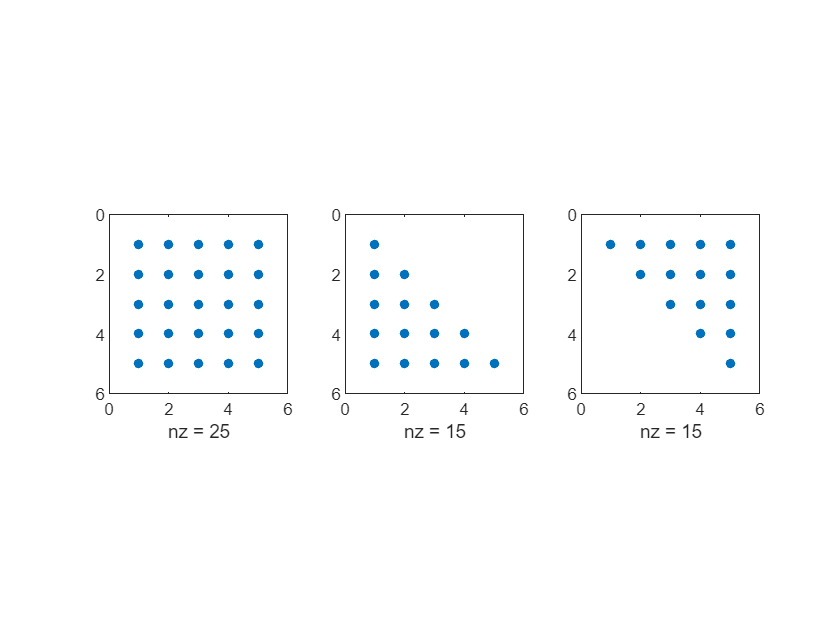

subplot(1,3,1)
spy(A),title(A); %sparsity pattern 结构
subplot(1,3,2)
spy(L),title(L); 
subplot(1,3,3)
spy(U),title(U); 

## 求解线性系统  Linear System

b=randn(n,1);
x=LUsolveLS(A,b);
disp('解为')

解为


disp(x)

    2.7200
   -2.4614
    1.0218
    1.9182
    1.3852



fprintf('误差：%f',norm(A*x-b))

误差：0.000000

disp(A*x-b)

   1.0e-15 *

   -0.8882
   -0.5551
   -0.6661
    0.2220
   -0.3331



function x=LUsolveLS(A,b)
    [L,U]=LU(A);
    [n,~]=size(A);
    %先求Ly=b
    y=ones(n,1)*b(1);
    for i=2:n
        y(i)=b(i)-L(i,1:i-1)*y(1:i-1);
    end
    x=y/U(n,n);
    for i=n-1:-1:1
        x(i)=(y(i)-U(i,i+1:n)*x(i+1:n))/U(i,i);
    end
end
function [L,U]=LU(A)
    [n,m]=size(A);
    if m~=n
        fprintf('\nError:A不是方阵！\n')
        return
    end
    L=eye(n);
    U=zeros(n);
    U(1,:)=A(1,:);
    L(2:end,1)=A(2:end,1)/U(1,1);
    for k=2:n
        for j=k:n
            U(k,j)=A(k,j)-L(k,1:k-1)*U(1:k-1,j);
        end
        for j=k:n
            L(j,k)=(A(j,k)-L(j,1:k-1)*U(1:k-1,k))/U(k,k);
        end
    end
end